# Sample 6-1

## 標本化

Sinc関数

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Sampling

Sinc function

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 標本化周期の設定

(Setting the sampling period)

- $\Delta_\mathrm{t}$: 標本化周期 (Sampling period)

% Sampling period
deltat = 1

deltat = 1

### Sinc関数

(Sinc function)

        
$$\mathrm{sinc}(\Delta_\mathbf{t}^{-1}t) \colon = \frac{\sin(\pi \Delta_\mathrm{t}^{-1}t)}{\pi \Delta_\mathrm{t}^{-1}t}$$


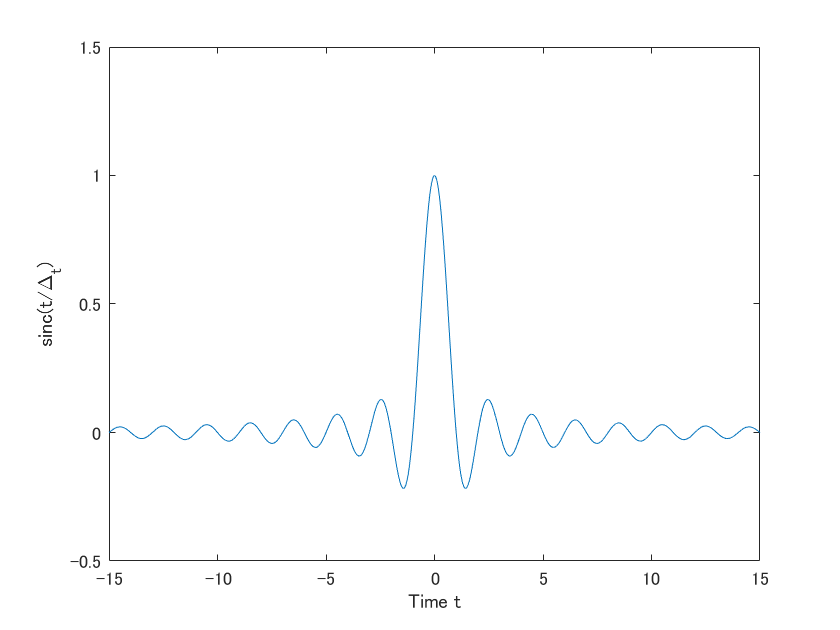

% Sinc function
figure(1)
fplot(@(x) sinc(x/deltat),[-15 15])
xlabel('Time t')
ylabel('sinc(t/\Delta_t)')
axis([-15 15 -0.5 1.5])

### 入力信号の設定

(Setting the input signal)

        
$$u(t) = \sum_{k\in\mathbb{Z}} c[k]\mathrm{sinc}
(\Delta_\mathrm{t}^{-1}t-k)$$


シャノンの標本化定理は帯域制限信号 (Shannon's sampling theorem is for the bandwidth-limiting signal )

         
$$u\in \mathrm{span}\{\mathrm{sinc}(\Delta_\mathrm{t}^{-1}\cdot-n)\}_n.$$


を対象とする。

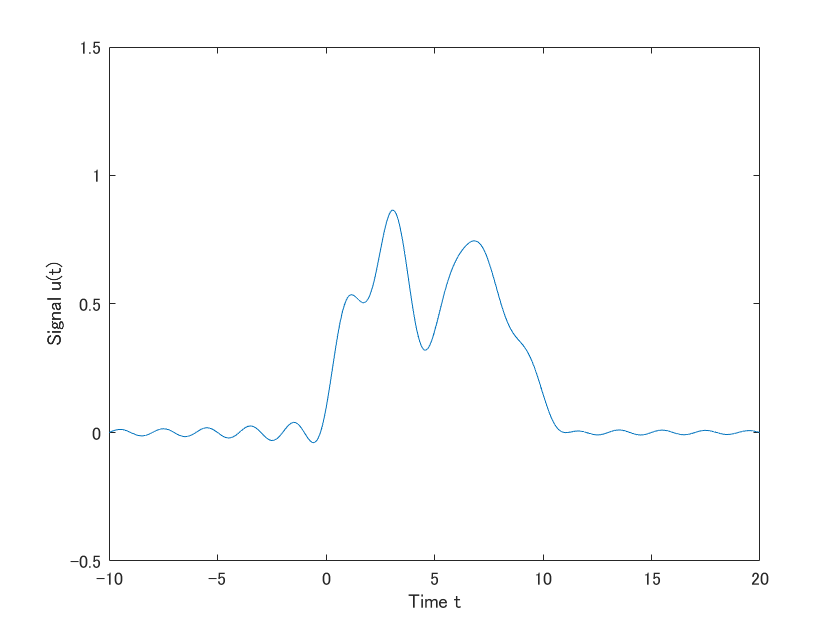

% Configuration
ts = -10;
te = 20;
k = 0:floor(10/deltat);
td = linspace(ts,te,(te-ts)*floor(1e3/deltat));
[Ts,K] = ndgrid(td,k);

% Generation of signal
c = rand(size(k));
u = sinc(Ts/deltat - K)*c(:);

% Plot the signal
figure(2)
plot(td,u)
xlabel('Time t')
ylabel('Signal u(t)')
axis([ts te -0.5 1.5])

### Sinc関数による標本化

### (Sampling with sinc function)

        
$$u[n] = \Delta_\mathrm{t}^{-1}\int_{-\infty}^{\infty}u(t)\mathrm{sinc}(\Delta_\mathrm{t}^{-1}t-n)dt$$


以下では有限なサポート領域および台形則で積分を近似していることに注意 (Note that the following approximates the integral with a finite support region and a trapezoidal law.)

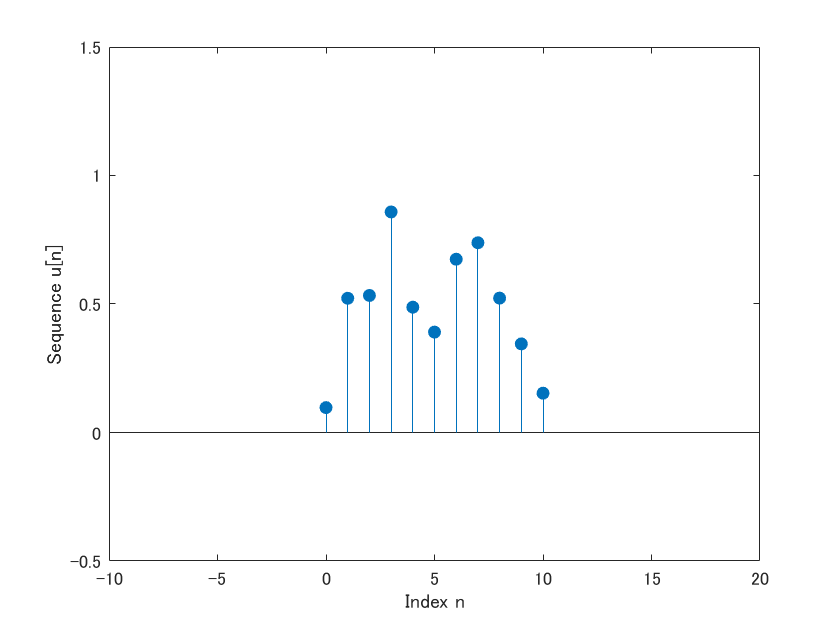

% Trapezoidal numerical integration
s = (1/deltat)*trapz(td,u.*sinc(Ts/deltat-K));

% Plot samples
figure(2)
stem(deltat*k,s,'filled')
xlabel('Index n')
ylabel('Sequence u[n]')
axis([ts te -.5 1.5])

### 信号再構成

(Signal reconstruction)

        
$$\hat{u}(t) = \sum_{k\in\mathbb{Z}} u[k]\mathrm{sinc}
(\Delta_\mathrm{t}^{-1}t-k)$$


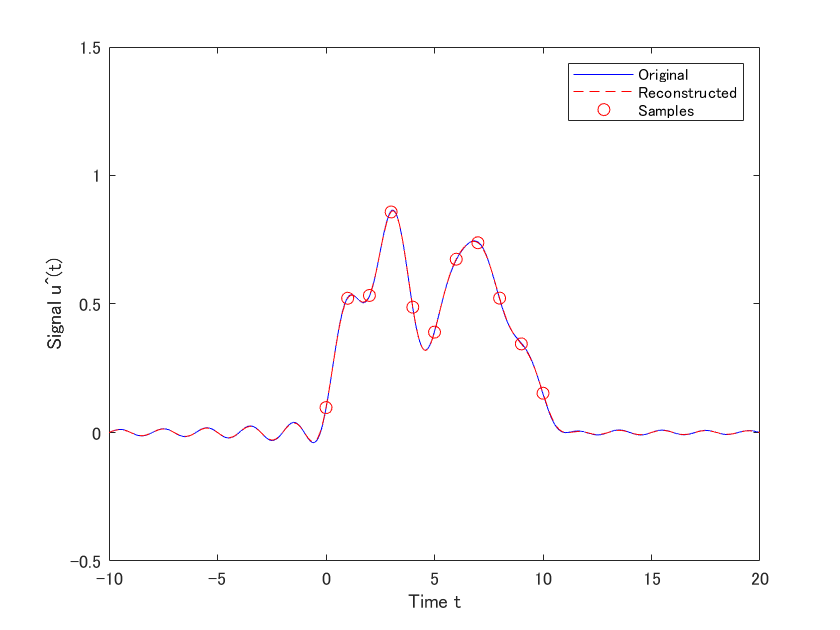

% Reconstruct the signal from the samples
uhat = sinc(Ts/deltat - K)*s(:);

% Plot the signal
figure(3)
plot(td,u,'b',td,uhat,'--r',deltat*k,s,'or')
xlabel('Time t')
ylabel('Signal u\^(t)')
axis([ts te -0.5 1.5])
legend('Original','Reconstructed','Samples')

© Copyright, Shogo MURAMATSU, All rights reserved.